clear
set(gcf,'renderer','Painters'); % Comando para mejorar la calidad al imprimir gráficas a PDF

## Parámetros de la planta (módulo termoeléctrico)

Tamb = 23.5 + 273.15;
Alpha = 0.041;
Rp = 0.82;
Kconvp = 0.20;
Krad = 9.59;
Kconva = 0.50;
mcecool = 9.2;
mcerad = 722.55;
mcehot = 13;
Vfan = 22;

## Condicion inicial del controlador, referencia y perturbaciones en el sistema (modo Set point Tracker o Disturbance Rejection)

Tipo = 'ST';
switch Tipo
    case 'ST' % Set Point Tracker
        Vin0 = 26;
        Reference = [0 4;60 4;60 2;80 2;80 6;100 6;100 5;120 5;120 1;140 1;140 4;200 4];
        Dist = [0 0;80 0;80 0;140 0;140 0; 200 0];
    case 'DR' % Disturbance Rejection
        Vin0 = 38;
        Reference = [0 -5;80 -5;80 -5;140 -5;140 -5; 200 -5];
        Dist = [0 0;80 0;80 -10;140 -10;140 0; 200 0];        
end

## Inicializa ganancias y matrices del LADRC

nx = 1; % Orden del LADRC
n = nx + 1;
b = -0.1028; % Valor nominal de la ganancia de control
wc = 0.5; % Ancho de banda del controlador
wo = 1; % Ancho de banda del LESO

K = zeros(1,nx); % Vector de ganancias del controlador proporcional
for i = 1:nx
        K(i) = (wc^(n-i))*((factorial(nx))/(factorial(i-1)*factorial(n-i)));
end
Cg = 1/b; % Ganancia de control
L = zeros(n,1); % Vector de ganancias del LESO
for i = 1:n
    L(i,1) = (wo^i)*((factorial(n))/(factorial(i)*factorial(n-i)));
end

% Matrices descriptoras del LADRC convencional
Ac = [zeros(n-1,1) eye(n-1);zeros(1,n)];
Bc = [zeros(nx-1,1);b;0];
Cc =[1 zeros(1,n-1)];

zo = [Tamb;zeros(n-1,1)]; % Estado inicial del LADRC

Ra = [Reference zeros(size(Reference,1),nx-1)];

## Corre las simulaciones de los modelos en Simulink

Tsim = 200; % Tiempo de simulación
sim('PID_PI_LADRC', Tsim);

## Gráfica de respuesta al escalón de la celda Peltier proceso no lineal

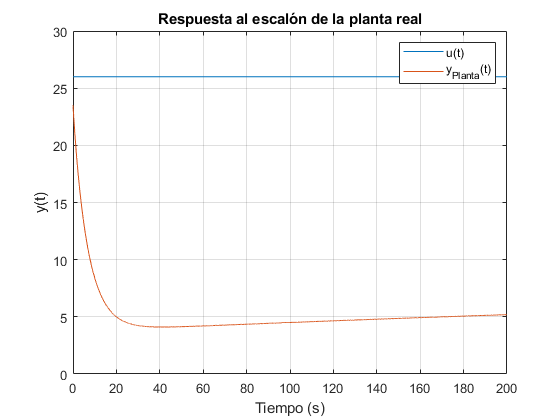

plot(respEscPlantaReal);
title('Respuesta al escalón de la planta real'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('y(t)'); % Etiqueta de eje vertical
legend('u(t)', 'y_{Planta}(t)');
grid;

## Gráfica de respuesta al escalón de planta aproximada

plot(respEscPlantaAprox);
title('Respuesta al escalón de la función transferencia obtenida'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('y(t)'); % Etiqueta de eje vertical
legend('u(t)', 'y_{Planta}(t)');
grid;


## Gráfica de respuesta del sistema, control PI sintonizado por polinomio caracteristico

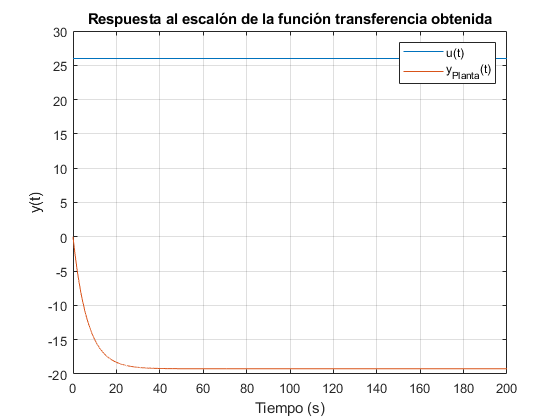

tiledlayout(2,1);

nexttile;
hold on;
plot(respControlPICalcu);
plot(referencia, ':');
hold off;
xlim([55 200]);
title('Respuesta del sistema con control PI'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Temperatura ({\circ} C)','Interpreter','tex'); % Etiqueta de eje vertical
legend('y(t)', 'r(t)');
grid;
nexttile
plot(respControlPICalcu_u);
xlim([55 200]);
title('Salida del controlador PI'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Tensión (%)'); % Etiqueta de eje vertical
legend('u(t)');
grid;

## Gráfica de respuesta del sistema, control PID sintonizado en SIMULINK

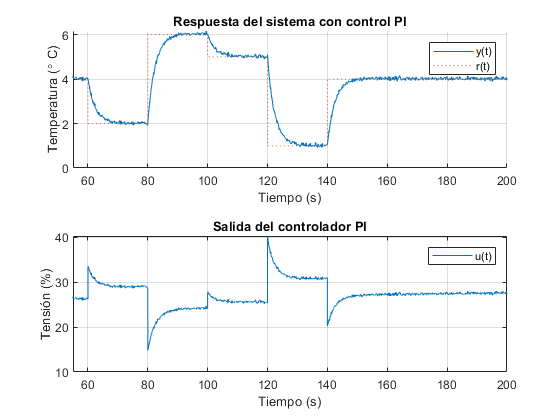

tiledlayout(2,1);

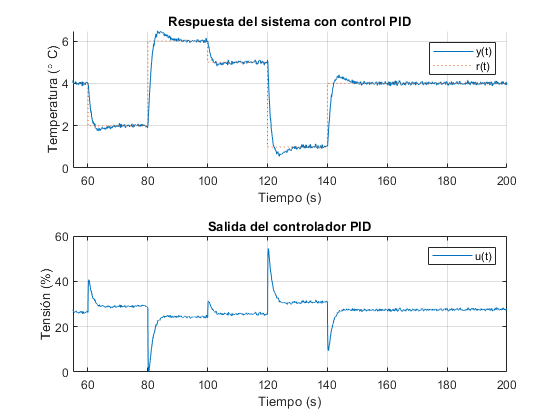

nexttile;
hold on;
plot(respControlPIDSIMUL);
plot(referencia, ':');
hold off;
xlim([55 200]);
title('Respuesta del sistema con control PID'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Temperatura ({\circ} C)','Interpreter','tex'); % Etiqueta de eje vertical
legend('y(t)', 'r(t)');
grid;
nexttile
plot(respControlPIDSIMUL_u);
xlim([55 200]);
title('Salida del controlador PID'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Tensión (%)'); % Etiqueta de eje vertical
legend('u(t)');
grid;

## Gráfica de respuesta del sistema, control LADRC

tiledlayout(2,1);
nexttile;
hold on;
plot(respLADRC);
plot(referencia, ':');
hold off;
xlim([55 200]);
title('Respuesta del sistema con control LADRC'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Temperatura ({\circ} C)','Interpreter','tex'); % Etiqueta de eje vertical
legend('y(t)', 'r(t)');
grid;
nexttile;
plot(respLADRC_u);
xlim([55 200]);
title('Salida del controlador LADRC'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Tensión (%)'); % Etiqueta de eje vertical
legend('u(t)');
grid;

## Gráfica comparativa de los sistemas de control diseñados

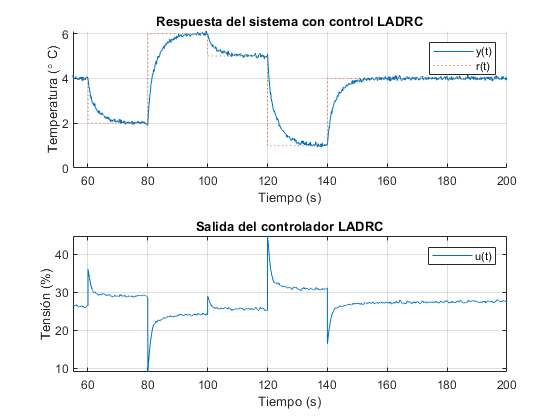

tiledlayout(2,1);

nexttile;
hold on;
plot(respControlPICalcu);
plot(respControlPIDSIMUL);
plot(respLADRC);
plot(referencia, ':');
hold off;
xlim([55 200]);
title('Respuesta del sistema: y(t)'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Temperatura ({\circ} C)','Interpreter','tex'); % Etiqueta de eje vertical
legend('PI','PID', 'LADRC', 'r(t)');
grid;
nexttile;
hold on;
plot(respControlPICalcu_u);
plot(respControlPIDSIMUL_u);
plot(respLADRC_u);
hold off;
xlim([55 200]);
title('Salida del controlador: u(t)'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Tensión (%)'); % Etiqueta de eje vertical
legend('PI','PID','LADRC');
grid;

## Simulación de LADRC en Python

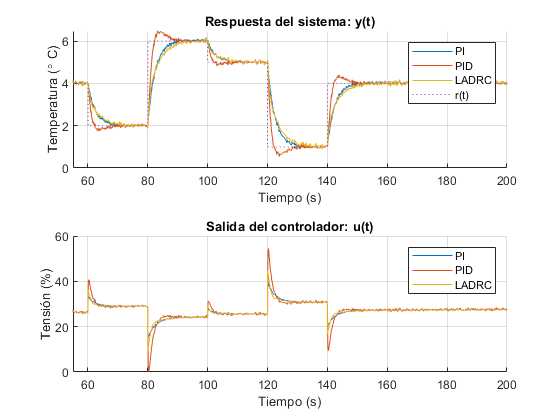

reloadPy()

sim('LADRC_Bloque_py', Tsim);

tiledlayout(2,1);

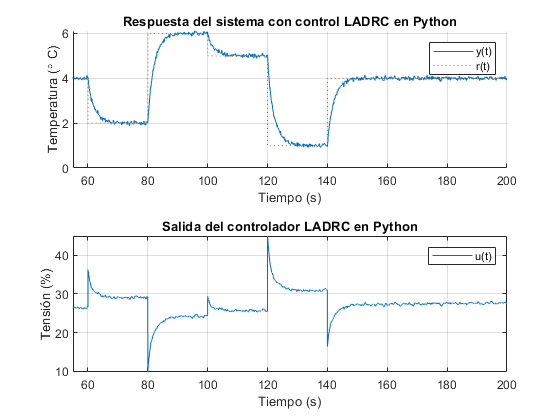

nexttile;
hold on;
plot(pyLADRC);
plot(referencia, ':');
hold off;
xlim([55 200]);
title('Respuesta del sistema con control LADRC en Python'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Temperatura ({\circ} C)','Interpreter','tex'); % Etiqueta de eje vertical
legend('y(t)', 'r(t)');
grid;
nexttile;
plot(pyLADRC_u);
xlim([55 200]);
title('Salida del controlador LADRC en Python'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Tensión (%)'); % Etiqueta de eje vertical
legend('u(t)');
grid;

tiledlayout(2,1);

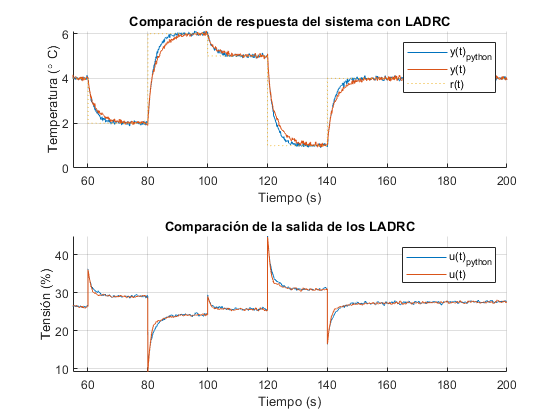

nexttile;
hold on;
plot(pyLADRC);
plot(respLADRC);
plot(referencia, ':');
hold off;
xlim([55 200]);
title('Comparación de respuesta del sistema con LADRC'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Temperatura ({\circ} C)','Interpreter','tex'); % Etiqueta de eje vertical
legend('y(t)_{python}', 'y(t)', 'r(t)');
grid;
nexttile;
hold on;
plot(pyLADRC_u);
plot(respLADRC_u);
hold off;
xlim([55 200]);
title('Comparación de la salida de los LADRC'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('Tensión (%)'); % Etiqueta de eje vertical
legend('u(t)_{python}', 'u(t)');
grid;

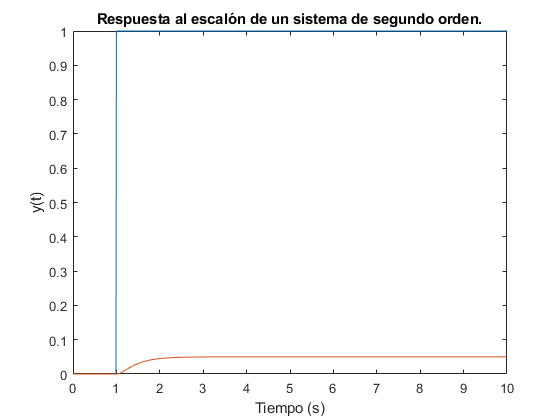


reloadPy()

sim('LADRC_Bloque_py_b', 10);
figure;
plot(respEscSegOrd);
title('Respuesta al escalón de un sistema de segundo orden.'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('y(t)'); % Etiqueta de eje vertical

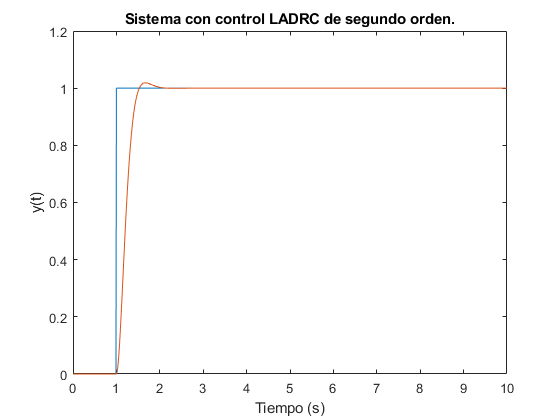

figure;
plot(secondOrderLADRC);
title('Sistema con control LADRC de segundo orden.'); % Título de gráfica
xlabel('Tiempo (s)'); % Etiqueta de eje horizontal
ylabel('y(t)'); % Etiqueta de eje vertical